# **Iniciação Científica**

#### Tema: Análise de Eficiência de Desacopladores e Técnicas de Projeto de Controladores PI SISO para Processos de Moagem

**Voluntária IC:** Grazielle Amanda do Carmo Café

**Orientador:** Dr. Márcio Braga

close all
clearvars

## **Modelo descrito por Ivezic e Petrovic (2003)**

### Etapa 1 - Desacopladores

% Descrição do Modelo: 
s = tf('s', 'TimeUnit', 'seconds');
G(1,1) = (-0.9362)/(1164*s + 1);
Ga(1,1) = exp(-350*s);
Gd(1,1) = -350;

G(1,2) = (10.252*s + 2.819*10^(-3))/(80218*s^2 + 652*s +1);
Ga(1,2) = exp(-200*s);
Gd(1,2) = -200; 

G(2,1) = (36.49)/(792*s+1);
Ga(2,1) = 1;
Gd(2,1) = 0; 

G(2,2) = (1.1405)/(179*s+1);
Ga(2,2) = 1;
Gd(2,2) = 0;

% Função de Transferência G: 
G;                        % Modelo sem atraso
Gdelay = Ga;              % Atrasos presentes no sistema
Gmodel = G.*Gdelay;       % Função de transferência G do modelo c/ atrasos        


**Desacoplador Estático**

**Teste 1**

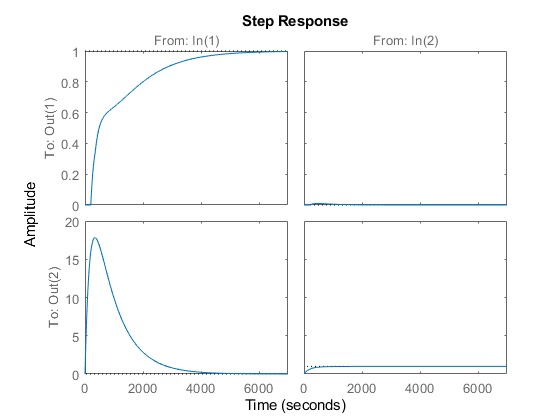

Gstatic = evalfr(Gmodel,0);
Dstatic = inv(Gstatic);
out = Gmodel*Dstatic;
step(out);

**Teste 2**

Comments: the conjugate model SYS' is noncausal when SYS has time delays

% Ginv = Gmodel';

**Teste 3**

%% detG = det(Gstatic)
% numGmodelStatic = [Gmodel(2,2) -Gmodel(1,2); -Gmodel(2,1) Gmodel(1,1)];
% denGmodelStatic = (Gmodel(1,1)*Gmodel(2,2)) - (Gmodel(1,2)*Gmodel(2,1));

%% Comments: O inverso de Gmodel é não causal devido aos atrasos
% Gmodel_inverse = mrdivide(numGmodelStatic,denGmodelStatic);

### Análise dos Índices de Desempenho

% [pv, t] = step(out)
% 
% sp = zeros(size(t,1),1);
% % sp = 0;
% erro = sp - pv;
% indice.IAE = trapz(abs(erro));
% indice.ITAE = trapz(t.*abs(erro));
% indice.ISE = trapz(erro.^2);


### Etapa 2 - Projeto de Controladores

### Técnica de Sintonia IMC

#### Controle C1 a partir de G(1,1): 

% k_1 = 1; 
% theta_1 = 350;
% tau_1 = 1164;
% tauc_1 = theta_1;
% 
% % Parâmetros
% kck_1 = (tau_1 + theta_1) / (k_1*(tauc_1 + theta_1));
% ti_1 = tau_1;
% ki_1 = kck_1 / ti_1; 
% td_1 = 0;
% kd_1 = kck_1 * td_1;
% 
% % Controle 
% C1 = pid(kck_1, ki_1, kd_1)
% 
% % Controle C2 a partir de G(2,2): 
% k_2 = 1; 
% tau_2 = 179;
% tauc_2 = tau_2 * 0.1;
% 
% % Parâmetros
% kck_2 = (tau_2) / (k_2*(tauc_2));
% ti_2 = tau_2;
% ki_2 = kck_2 / ti_2; 
% td_2 = 0;
% kd_2 = kck_2 * td_2;
% 
% % Controle 
% C2 = pid(kck_2, ki_2, kd_2)
% 
% % % Simulação
% % spaceG11 = ss(Gmodel(1,1));
% % spaceG12 = ss(Gmodel(1,2));
% % spaceG21 = ss(Gmodel(2,1));
% % spaceG22 = ss(Gmodel(2,2));
% % 
% % % Did = eye(2,2);
% % 
% % sim('Simulink_Ivezic_2x2.slx')
